# **Deflection Analysis of Bracket**

This example shows how to analyze a 3-D mechanical part under an applied load using the finite element analysis model and determine the maximal deflection.

Matlab examples see [Partial Differential Equation Toolbox](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html).

### Partial Differential Equation Toolbox Solving

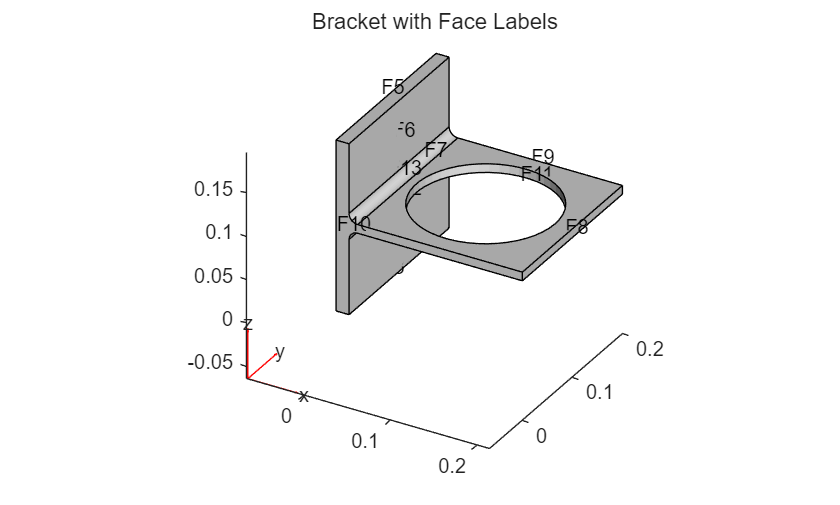

clc; clear;

E  = 200e9;
nu = 0.3;
rho = 0.0;

model = femodel(AnalysisType="structuralStatic", ...
                Geometry="BracketWithHole.stl");

model.MaterialProperties = materialProperties( ...
    YoungsModulus = E, ...
    PoissonsRatio = nu);

model.FaceBC(4) = faceBC(Constraint="fixed");
model.FaceLoad(8) = faceLoad(SurfaceTraction=[0;0;-1e4]);

figure
pdegplot(model,FaceLabels="on");
view(30,30);
title("Bracket with Face Labels")

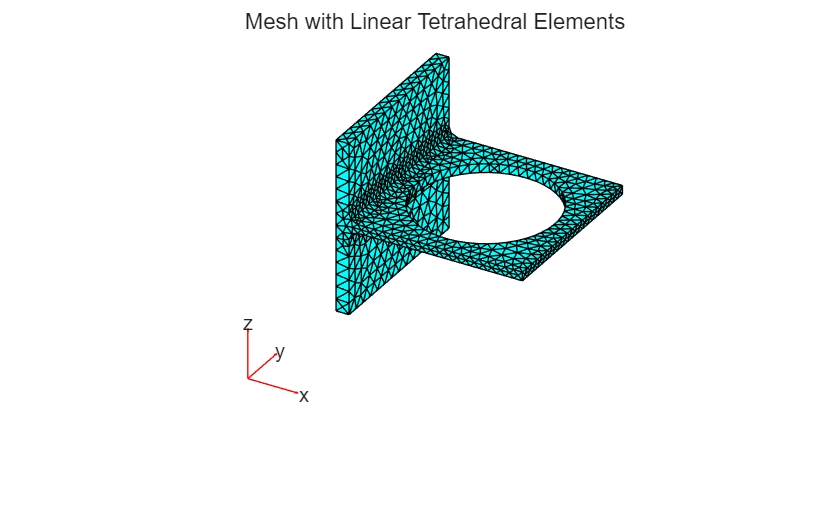

pdeModel = generateMesh(model, GeometricOrder="linear");

figure
pdemesh(pdeModel);
title("Mesh with Linear Tetrahedral Elements")

result = solve(pdeModel);
minUzPDE = min(result.Displacement.uz);
fprintf("Maximal deflection in the z-direction is %g meters.",minUzPDE)

Maximal deflection in the z-direction is -1.44604e-05 meters.

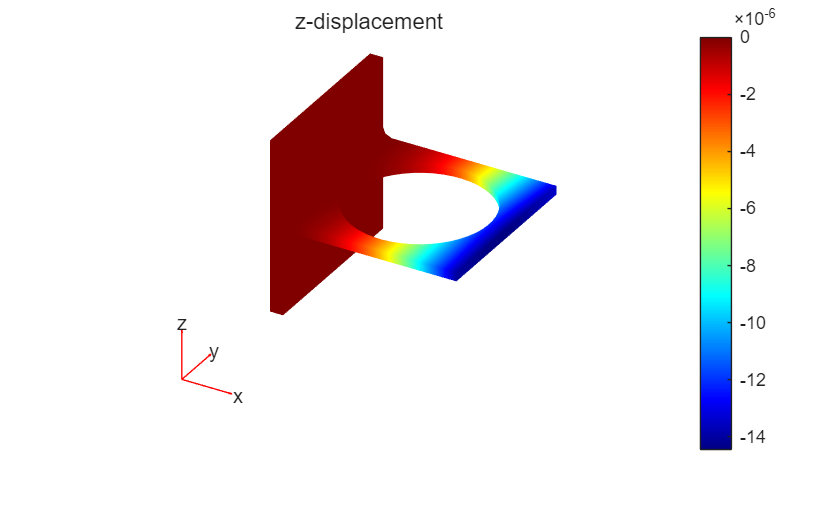

figure
pdeplot3D(result.Mesh,ColorMapData=result.Displacement.uz);
title("z-displacement");
colormap("jet")

[az, el] = view;

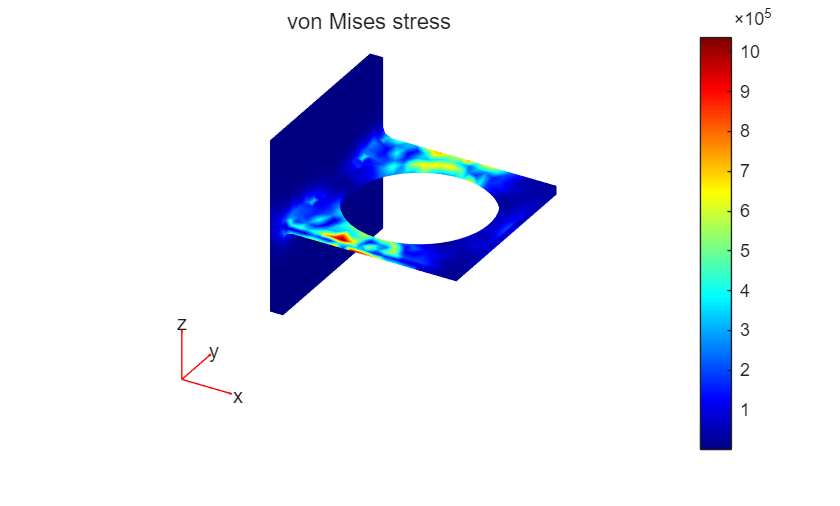

figure
pdeplot3D(result.Mesh,ColorMapData=result.VonMisesStress)
title("von Mises stress")
colormap("jet")

maxVonMisesStressPDE = max(result.VonMisesStress);
fprintf("Maximal VonMisesStress is %g Pa.", maxVonMisesStressPDE)

Maximal VonMisesStress is 1.03705e+06 Pa.

### OpenSeesMatlab Solving

#### Extract PDE mesh data

mesh = pdeModel.Mesh;

% PDE toolbox:
%   mesh.Nodes    : 3 x nNode
%   mesh.Elements : nNodePerElem x nElem
nodes = mesh.Nodes.';        % nNode x 3
elems = mesh.Elements.';     % nElem x nen

nNode = size(nodes,1);
nElem = size(elems,1);
nen   = size(elems,2);

if nen ~= 4
    error(['This script currently expects linear 4-node tetrahedra. ', ...
           'Please use generateMesh(..., GeometricOrder="linear").']);
end

%% ------------------------------------------------------------------------
% Find face nodes for fixed boundary and loaded boundary
%% ------------------------------------------------------------------------
fixedFaceID  = 4;
loadedFaceID = 8;
traction     = [0; 0; -1e4];   % N/m^2

fixedNodeIDs = findNodes(mesh, "region", "Face", fixedFaceID);
loadNodeIDs  = findNodes(mesh, "region", "Face", loadedFaceID);

fixedNodeIDs = unique(fixedNodeIDs(:));
loadNodeIDs  = unique(loadNodeIDs(:));

%% ------------------------------------------------------------------------
% Build boundary triangles on the loaded face and convert traction
%    to equivalent nodal loads
%% ------------------------------------------------------------------------
% For a tetra mesh, each tetra has 4 triangular faces.
% Boundary faces are those triangle faces that appear only once.
allBoundaryTris = getBoundaryTrianglesFromTets(elems);

% Keep only boundary triangles whose 3 nodes are all on Face 8
isOnLoadFace = all(ismember(allBoundaryTris, loadNodeIDs.'), 2);
loadFaceTris = allBoundaryTris(isOnLoadFace, :);

if isempty(loadFaceTris)
    warning('No boundary triangles were found on loaded Face %d.', loadedFaceID);
end

% Assemble nodal force vector from surface traction
nodalLoads = zeros(nNode, 3);

for i = 1:size(loadFaceTris,1)
    tri = loadFaceTris(i,:);
    xyz = nodes(tri, :);              % 3 x 3
    A   = triangleArea3D(xyz);

    % Constant traction on linear triangle:
    % equivalent nodal load = traction * A / 3 for each of 3 nodes
    fe = (A / 3) * traction(:);       % 3 x 1 for one node
    nodalLoads(tri, :) = nodalLoads(tri, :) + repmat(fe.', 3, 1);
end

#### Build OpenSees model

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

ops.wipe();
ops.model('basic', '-ndm', 3, '-ndf', 3);

% Nodes
for i = 1:nNode
    ops.node(i, nodes(i,1), nodes(i,2), nodes(i,3));
end

% Material
matTag = 1;
E  = 200e9;
nu = 0.3;
rho = 0.0;

% 3D isotropic elastic material
ops.nDMaterial('ElasticIsotropic', matTag, E, nu, rho);

% Elements: 4-node tetrahedra
for e = 1:nElem
    n = elems(e,:);
    ops.element('FourNodeTetrahedron', e, n(1), n(2), n(3), n(4), matTag);
end

% Apply fixed boundary from PDE Face 4
for k = 1:numel(fixedNodeIDs)
    nd = fixedNodeIDs(k);
    ops.fix(nd, 1, 1, 1);
end

% Apply equivalent nodal loads from PDE Face 8 traction
ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);

tol = 0;
for i = 1:nNode
    fx = nodalLoads(i,1);
    fy = nodalLoads(i,2);
    fz = nodalLoads(i,3);

    if abs(fx) > tol || abs(fy) > tol || abs(fz) > tol
        ops.load(i, fx, fy, fz);
    end
end

% Static analysis
ops.constraints('Plain');
ops.numberer('RCM');
ops.system('BandGeneral');
ops.test('NormDispIncr', 1e-8, 50);
ops.algorithm('Linear');
ops.integrator('LoadControl', 1.0/10);
ops.analysis('Static');

ODB = opsMAT.post.createODB("myODB");  % create ODB
for i = 1:10
    ok = ops.analyze(1);
    ODB.fetchResponseStep();
end
ODB.saveResponse();

[OpenSeesMatlab] odbTag=myODB saved → .openseesmatlab.output\Responses-myODB.odb


#### Visualization by OpenSeesMatlab

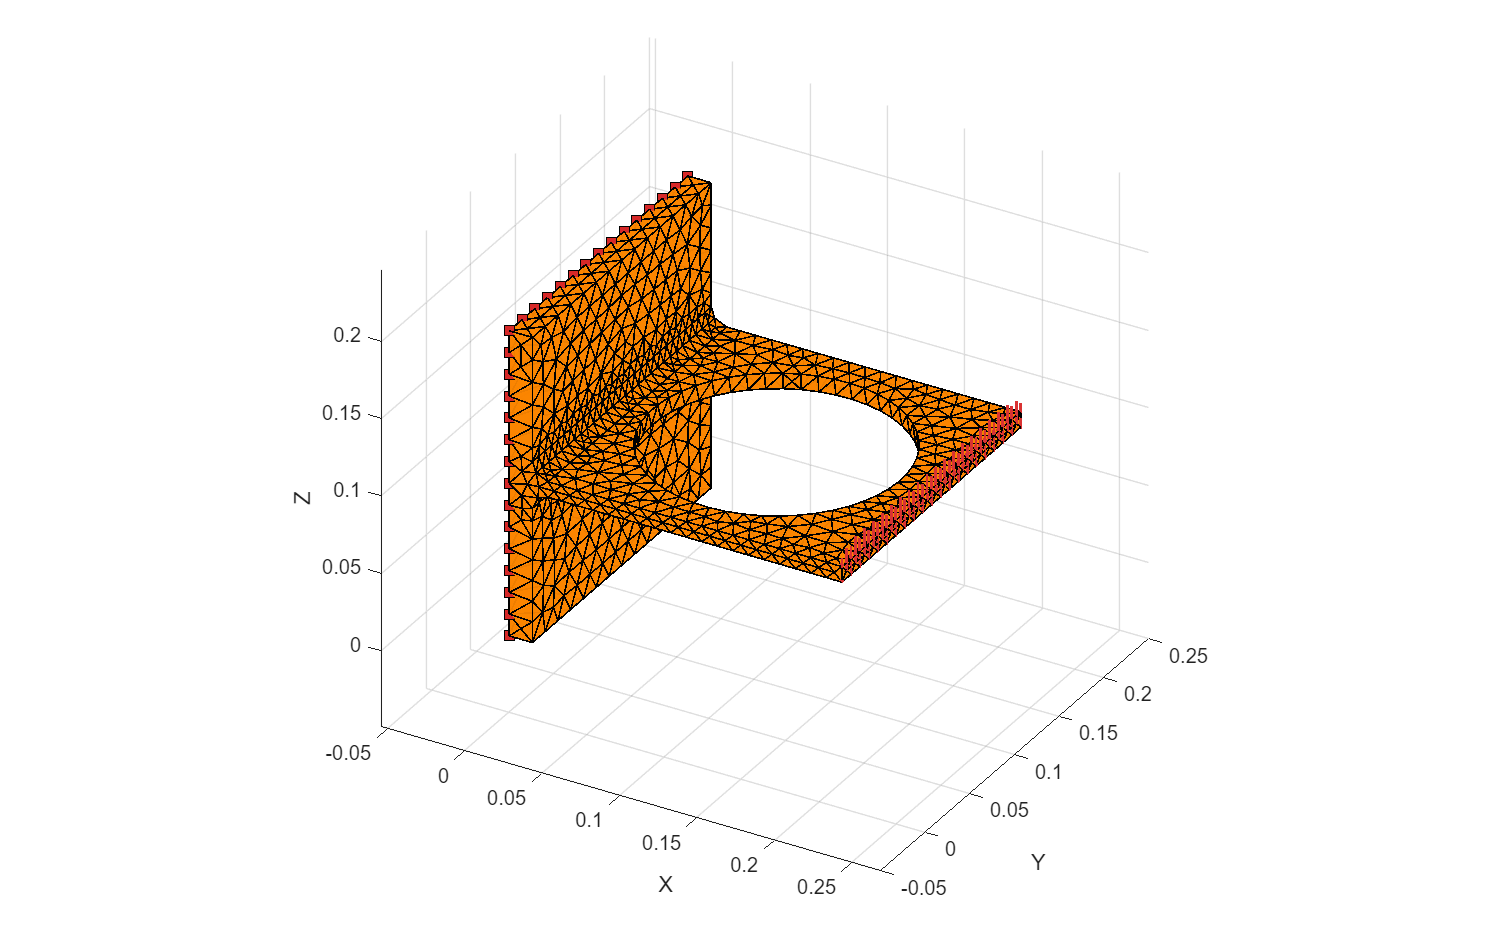

opts = opsMAT.vis.defaultPlotModelOptions;
opts.loads.showNodal=true;
opsMAT.vis.plotModel(opts=opts);
view(az, el);

nodeResp = opsMAT.post.getNodalResponse("myODB");
uz = nodeResp.disp.uz;
minUz = min(uz(:));
fprintf("Maximal deflection in the z-direction:\n" + ...
        "  OpenSeesMatlab: %g meters\n" + ...
        "  MATLAB PDE    : %g meters\n", ...
        minUz, minUzPDE);

Maximal deflection in the z-direction:
  OpenSeesMatlab: -1.44604e-05 meters
  MATLAB PDE    : -1.44604e-05 meters


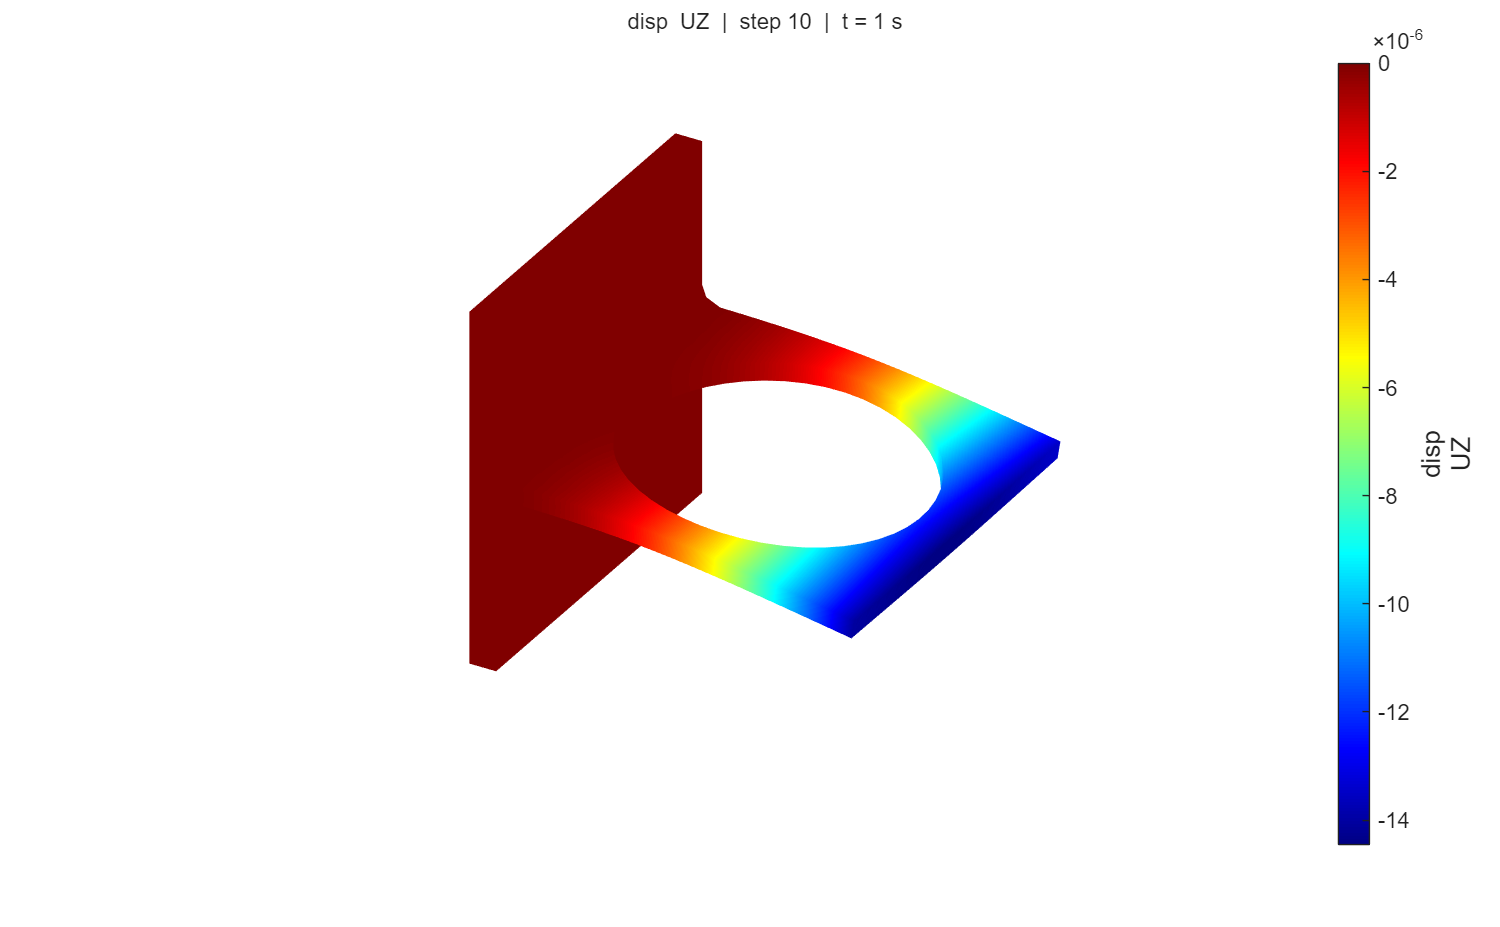

opts = opsMAT.vis.defaultPlotNodalResponseOptions;
opts.fixed.show = false;
opts.surf.showEdges = false;

opsMAT.vis.plotNodalResponse(nodeResp, respType="disp", stepIdx="absMax", respComponent="UZ", opts=opts);
colormap("jet")
axis off
view(az, el);

solidResp = opsMAT.post.getElementResponse("myODB", eleType="Solid");
vm = solidResp.StressMeasureAtNode.sigmaVM;
maxVonMisesStress = max(vm(:));
fprintf("Maximal Von Mises stress:\n" + ...
        "  OpenSeesMatlab: %g Pa\n" + ...
        "  MATLAB PDE    : %g Pa\n", ...
        maxVonMisesStress, maxVonMisesStressPDE);

Maximal Von Mises stress:
  OpenSeesMatlab: 1.03705e+06 Pa
  MATLAB PDE    : 1.03705e+06 Pa


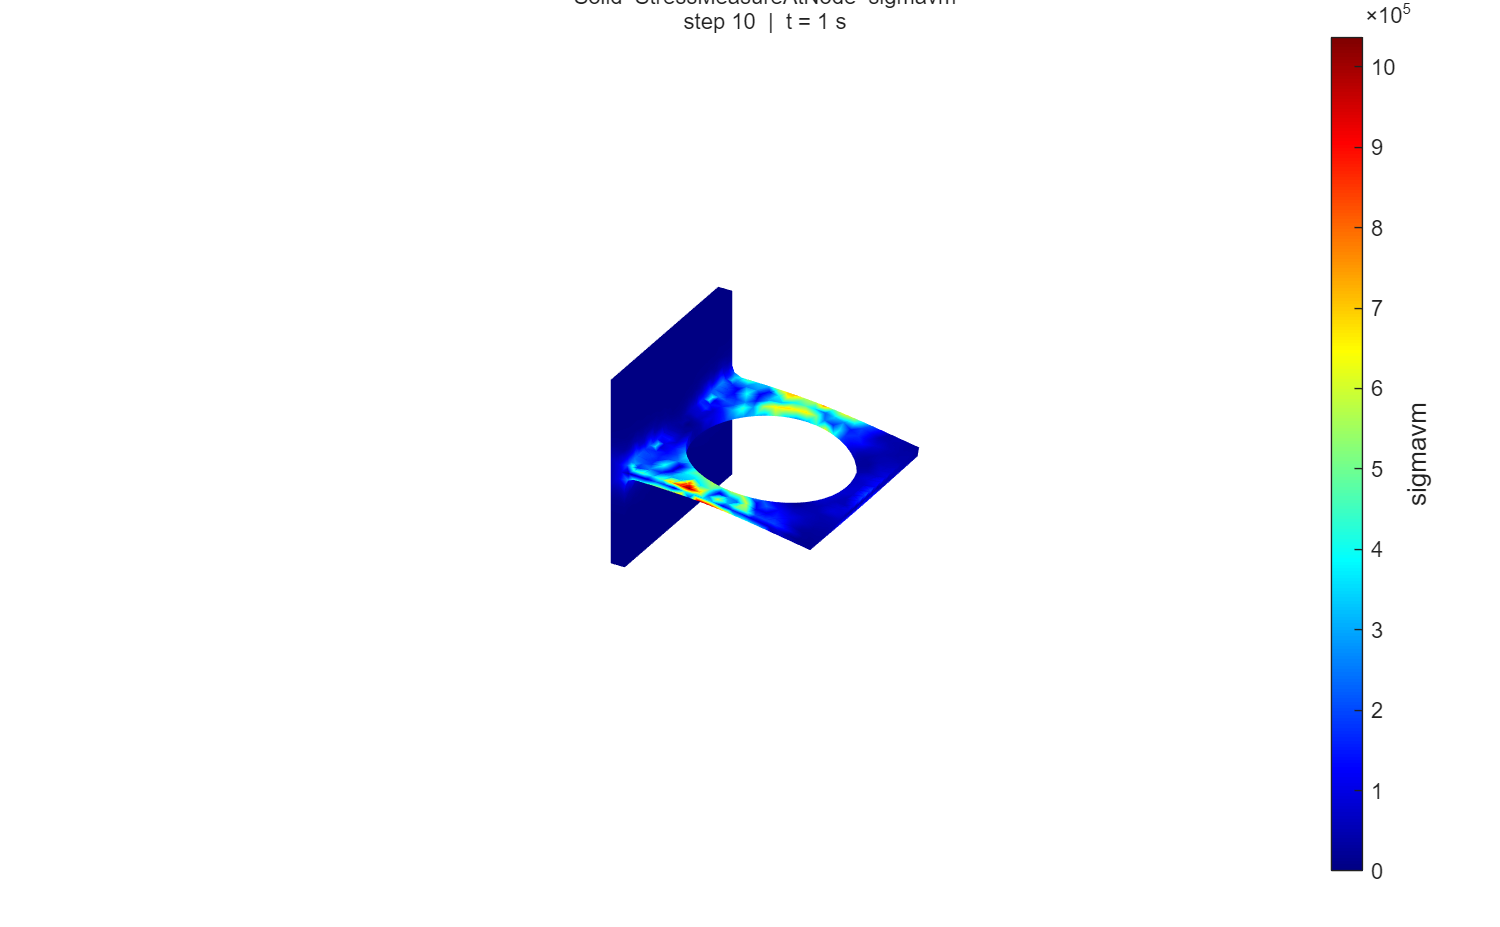



opts = opsMAT.vis.defaultPlotContinuumResponseOptions;
opts.fixed.show = false;
opts.surf.showEdges = false;

opsMAT.vis.plotContinuumResponse(solidResp, ...
    respType="StressMeasureAtNodes", respComponent="sigmaVM", opts=opts);
axis off
colormap("jet")
view(az, el);

### Local functions

%% ------------------------------------------------------------------------
% Local functions
%% ------------------------------------------------------------------------
function btris = getBoundaryTrianglesFromTets(tets)
%GETBOUNDARYTRIANGLESFROMTETS Return unique boundary triangle faces
% tets: nElem x 4

    f1 = tets(:, [1 2 3]);
    f2 = tets(:, [1 2 4]);
    f3 = tets(:, [1 3 4]);
    f4 = tets(:, [2 3 4]);

    allFaces = [f1; f2; f3; f4];
    allFacesSorted = sort(allFaces, 2);

    [uFaces, ~, ic] = unique(allFacesSorted, 'rows');
    counts = accumarray(ic, 1);

    isBoundary = counts(ic) == 1;
    boundaryFacesSorted = allFacesSorted(isBoundary, :);

    % Keep orientation-free representation
    btris = boundaryFacesSorted;
end

function A = triangleArea3D(xyz)
%TRIANGLEAREA3D Area of a 3D triangle
% xyz: 3 x 3, each row is one node coordinate

    v1 = xyz(2,:) - xyz(1,:);
    v2 = xyz(3,:) - xyz(1,:);
    A = 0.5 * norm(cross(v1, v2));
end